# Create Simulink Environment and Train Agent

This example shows how to convert the PI controller in the `watertank` Simulink® model to a reinforcement learning deep deterministic policy gradient (DDPG) agent. For an example that trains a DDPG agent in MATLAB®, see [Train DDPG Agent to Balance Double Integrator Environment](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

## 2d manipulator Model

Modify the original model by making the following changes:

- Delete the PID Controller.

- Insert the RL Agent block.

- Connect the observation vector ${\left\lbrack \begin{array}{ccc}
\int e\;\textrm{dt} & e & h
\end{array}\right\rbrack }^{T\;}$, where $h$ is the height of the tank, $e=r-h$, and $r$ is the reference height.

- Set up the reward $\mathrm{reward}=10\left(\left|e\right|<0\ldotp 1\right)-1\left(\left|e\right|\ge 0\ldotp 1\right)-100\left(h\le 0\left|\right|h\ge 20\right)$.

- Configure the termination signal such that the simulation stops if $h\le 0$ or $h\ge 20$.

The resulting model is `rlwatertank.slx`. For more information on this model and the changes, see [Create Simulink Environment for Reinforcement Learning](docid:rl_ug#mw_0e8060ca-2e7a-4d41-90d1-3bf4aeb76099).

clc, clear, close all
load('q2.mat');
load('q4.mat');

[x_ee, y_ee] = ForwardKinematics(q2, q4);
res      = 10000;    % res is resolution of the output look-up-table
T        = 1;        % T is period of x in second
sm_param = 0.999999; % sm_param is SmoothingSpline fitting parameter the higher the more bias

[~   ,tt,Radius_1,Acceleration_1,Pitch_1,X1,V1,Center_1,Transformation_1,S1] ...
      = ver_toolbox(q2,T,res,sm_param,1);

[~   ,~ ,Radius_2,Acceleration_2,Pitch_2,X2,V2,Center_2,Transformation_2,S2] ...
      = ver_toolbox(q4,T,res,sm_param,1);

%%
q0 = [-pi/4 -3*pi/4];
w0 = 0.*[(q2(2)-q2(1))/(T/length(q2)) (q4(2)-q4(1))/(T/length(q4))];
% w0 = [(q2(2)-q2(1))/(0.01), (q4(2)-q4(1))/(0.01)];
P  = 0*50;
% D  = 10;
D = 0; 
sr = 0.01;
en = 1;

open_system('panda')

## Create the Environment Interface

Creating an environment model includes defining the following:

- Action and observation signals that the agent uses to interact with the environment. For more information, see [rlNumericSpec](docid:rl_ref#mw_1a66fdf2-e758-4985-a541-61943fb15e79) and [rlFiniteSetSpec](docid:rl_ref#mw_68f70adf-d6a9-4cbe-846c-a7d0823c0774).

- Reward signal that the agent uses to measure its success. For more information, see [Define Reward Signals](docid:rl_ug#mw_1fe437df-5904-43dc-8b75-1e25bb9ae3ff).

Define the observation specification `obsInfo` and action specification `actInfo`.

obsInfo = rlNumericSpec([8 1],...
    LowerLimit=[-inf -inf -inf -inf -inf -inf -inf -inf]',...
    UpperLimit=[inf inf inf inf inf inf inf inf]');
obsInfo.Name = "observations";
obsInfo.Description = "pos1, vel1, error1, error_dot1, pos2, vel2, error2, error_dot2";

actInfo = rlNumericSpec([2 1]);
actInfo.Name = "torque1, torque2";

Build the environment interface object.

env = rlSimulinkEnv("panda","panda/RL/RL Agent",obsInfo,actInfo);

Set a custom reset function that randomizes the reference values for the model.

env.ResetFcn = @(in)localResetFcn(in);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

% Ts = 1.0;
Ts = 1/20;
Tf = 10;

Fix the random generator seed for reproducibility.

rng(0)

## Create the Critic

Given observations and actions, a DDPG agent approximates the long-term reward using a value function approximator as a critic.

Create a deep neural network to approximate the value function within the critic. To create a network with two inputs, the observation and action, and one output, the value, use three different paths, and specify each path as a row vector of layer objects. You can obtain the dimension of the observation and action spaces from the `obsInfo` and `actInfo` specifications. 

statePath = [
    featureInputLayer(obsInfo.Dimension(1),Name="netObsIn")
    fullyConnectedLayer(120)
    reluLayer
    fullyConnectedLayer(80,Name="CriticStateFC2")];

actionPath = [
    featureInputLayer(actInfo.Dimension(1),Name="netActIn")
    fullyConnectedLayer(80,Name="CriticActionFC1")];

commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(1,Name="CriticOutput")];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);

criticNetwork = connectLayers(criticNetwork, ...
    "CriticStateFC2", ...
    "add/in1");
criticNetwork = connectLayers(criticNetwork, ...
    "CriticActionFC1", ...
    "add/in2");

View the critic network configuration.

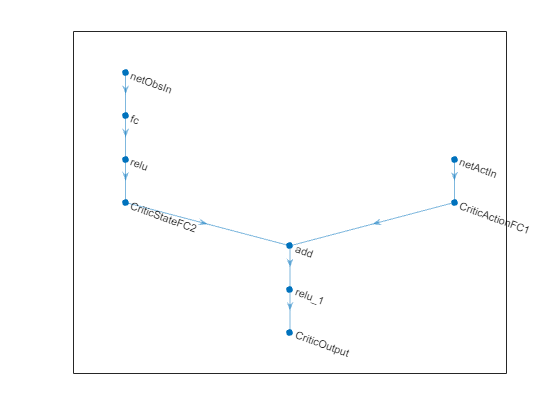

figure
plot(criticNetwork)

Convert the network to a `dlnetwork` object and summarize its properties.

criticNetwork = dlnetwork(criticNetwork);
summary(criticNetwork)

   Initialized: true
   Number of learnables: 11k
   Inputs:
      1   'netObsIn'   8 features
      2   'netActIn'   2 features


Create the critic approximator object using the specified deep neural network, the environment specification objects, and the names if the network inputs to be associated with the observation and action channels. 

critic = rlQValueFunction(criticNetwork,obsInfo,actInfo, ...
    ObservationInputNames="netObsIn", ...
    ActionInputNames="netActIn");

For more information on Q-value function objects, see [`rlQValueFunction`](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

Check the critic with a random input observation and action.

getValue(critic, ...
    {rand(obsInfo.Dimension)}, ...
    {rand(actInfo.Dimension)})

ans = single
0.2952

For more information on creating critics, see [Create Policies and Value Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

## Create the Actor

Given observations, a DDPG agent decides which action to take using a deterministic policy, which is implemented by an actor.

Create a deep neural network to approximate the policy within the actor. To create a network with one input, the observation, and one output, the action, a row vector of layer objects. You can obtain the dimension of the observation and action spaces from the `obsInfo` and `actInfo` specifications. 

actorNetwork = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(8)
    tanhLayer
    fullyConnectedLayer(actInfo.Dimension(1))
    ];

Convert the network to a `dlnetwork` object and summarize its properties.

actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true
   Number of learnables: 90
   Inputs:
      1   'input'   8 features


Create the actor approximator object using the specified deep neural network, the environment specification objects, and the name if the network input to be associated with the observation channel. 

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

For more information, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3). 

Check the actor with a random input observation.

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {2×1 single}

For more information on creating critics, see [Create Policies and Value Functions](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

## Create the Agent

Create the DDPG agent using the specified actor and critic approximator objects.

for AgentSelection = ["DDPG", "TD3"]

switch AgentSelection
    case 'DDPG'
%         agent = createDDPGAgent(numObs,obsInfo,numAct,actInfo,Ts);
        agent = rlDDPGAgent(actor, critic);
    case 'TD3'
%         agent = createTD3Agent(numObs,obsInfo,numAct,actInfo,Ts);
        agent = rlTD3Agent(actor,critic);
%     otherwise
%         disp('Enter DDPG or TD3 for AgentSelection')
end

% agent = rlDDPGAgent(actor,critic);

For more information, see [rlDDPGAgent](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef). 

Specify options for the agent, the actor, and the critic using dot notation.

agent.SampleTime = Ts;

agent.AgentOptions.TargetSmoothFactor = 1e-3;
agent.AgentOptions.DiscountFactor = 1.0;
agent.AgentOptions.MiniBatchSize = 64;
agent.AgentOptions.ExperienceBufferLength = 1e6; 

% agent.AgentOptions.NoiseOptions.Variance = 0.3;
% agent.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

Alternatively, you can specify the agent options using an [rlDDPGAgentOptions](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c) object.

Check the agent with a random input observation.

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {2×1 double}

ans = 1×1 cell array
    {2×1 double}

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run each training for at most `5000` episodes. Specify that each episode lasts for at most `ceil(Tf/Ts)` (that is `200`) time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than `800` over `20` consecutive episodes. At this point, the agent can control the level of water in the tank.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

max_episodes = 1000;
trainOpts = rlTrainingOptions(...
    MaxEpisodes=max_episodes, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=20, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="EpisodeCount",...
    StopTrainingValue=max_episodes, ...
    SaveAgentCriteria='EpisodeCount',...
    SaveAgentValue=max_episodes)

trainOpts =   rlTrainingOptions with properties:

                   MaxEpisodes: 1000
            MaxStepsPerEpisode: 200
    ScoreAveragingWindowLength: 20
          StopTrainingCriteria: "EpisodeCount"
             StopTrainingValue: 1000
             SaveAgentCriteria: "EpisodeCount"
                SaveAgentValue: 1000
            SaveAgentDirectory: "savedAgents"
                       Verbose: 0
                         Plots: "training-progress"
                   StopOnError: "on"
                   UseParallel: 0
        ParallelizationOptions: [1×1 rl.option.ParallelTraining]

trainOpts =   rlTrainingOptions with properties:

                   MaxEpisodes: 1000
            MaxStepsPerEpisode: 200
    ScoreAveragingWindowLength: 20
          StopTrainingCriteria: "EpisodeCount"
             StopTrainingValue: 1000
             SaveAgentCriteria: "EpisodeCount"
                SaveAgentValue: 1000
            SaveAgentDirectory: "savedAgents"
                       Verbose: 0
                         Plots: "training-progress"
                   StopOnError: "on"
                   UseParallel: 0
        ParallelizationOptions: [1×1 rl.option.ParallelTraining]

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;
seed = 3;
if doTraining
    % Train the agent.
    for i = 1:3
        trainingStats = train(agent,env,trainOpts);
        if strcmp(AgentSelection,'DDPG')
            name = strcat("/run", num2str(i), ".mat");
            save("DDPGAgent" + name,'trainingStats')
            
        else
            name = strcat("/run", num2str(i), ".mat");
            save("TD3Agent" + name,'trainingStats')
        end
    end
end

Found algebraic loop containing: 
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/INPUT_1_1_1
panda/ARM/Subsystem/Gain3
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/INPUT_2_1_1
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/OUTPUT_1_1
panda/ARM/Subsystem/Gain2
panda/Mass Matrix/Gain4
panda/ARM/G/Gain2

Found algebraic loop containing: 
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/INPUT_1_1_1
panda/ARM/Subsystem/Gain3
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/INPUT_2_1_1
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/OUTPUT_1_1
panda/ARM/Subsystem/Gain2
panda/Mass Matrix/Gain4
panda/ARM/G/Gain2

Found algebraic loop containing: 
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/INPUT_1_1_1
panda/ARM/Subsystem/Gain3
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/INPUT_2_1_1
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/OUTPUT_1_1
panda/ARM/Subsystem/Gain2
panda/Mass Matrix/Gain4
panda/ARM/G/Gain2

Found algebraic loop containing: 
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/INPUT_1_1_1
panda/ARM/Subsystem/Gain3
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/INPUT_2_1_1
panda/ARM/Subsystem/Solver Configuration/EVAL_KEY/OUTPUT_1_1
panda/ARM/Subsystem/Gain2
panda/Mass Matrix/Gain4
panda/ARM/G/Gain2

## Validate Trained Agent

Validate the learned agent against the model by simulation.

simOpts = rlSimulationOptions(MaxSteps=ceil(Tf/Ts),StopOnError="on");
experiences = sim(env,agent,simOpts);
end
figure(Position=[840 558 400 229])
comparePerformance("DDPGAgent", "TD3Agent")

## Local Function

function in = localResetFcn(in)

% randomize reference signal - amplitude
blk = sprintf('panda/PD/amplitude');
h = 1;
% h = 0.3*randn + 0.8;
% while h <= 0.8 || h >= 1.3
%     h = 0.3*randn + 0.8;
% end
in = setBlockParameter(in,blk,'Value',num2str(h));

% randomize reference signal - period
blk = sprintf('panda/PD/period');
h = 0.8*randn + 1.25;
while h < 1 || h > 2
    h = 0.8*randn + 1.25;
end
in = setBlockParameter(in,blk,'Value',num2str(h));


end

*Copyright 2019 The MathWorks, Inc.*